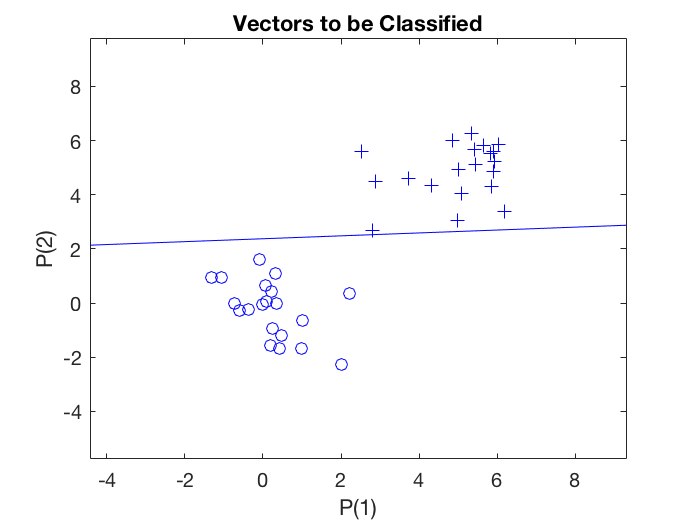

% Task 4
close all, clear all  clc;
% number of samples of each class
N = 20;
% define inputs and outputs
offset = 5; % offset for second class
x = [randn(2,N) randn(2,N)+offset]; % inputs
y = [zeros(1,N) ones(1,N)]; % outputs
% Plot input samples with plotpv (Plot perceptron input/target vectors) figure(1)
plotpv(x,y);

%instantiate the perceptron 
net = perceptron;

%training the network
net = train(net, x,y);
%view(net);

%plotting the decision boundary 
figure(1)
plotpc(net.IW{1},net.b{1});